# Constant current


Starting wave glider path planning...
Goal reached in 3578 iterations with wave glider dynamics.
Wave Glider Path Stats:
  Path length: 122.88 m
  Total time: 295.8 s
  Average ground speed: 0.42 m/s
  Waypoints: 1479
  Total turning: 36.06 rad (2066.1 deg)

Starting wave glider path planning...
Maximum iterations reached. Goal may not be reachable with wave glider constraints.
Wave Glider Path Stats:
  Path length: 44.21 m
  Total time: 123.0 s
  Average ground speed: 0.36 m/s
  Waypoints: 615
  Total turning: 19.87 rad (1138.4 deg)

--- Wave Glider Parameters ---
Average Speed: 0.36 m/s
Turning Radius: 1.13 m
Max Turn Rate: 0.319 rad/s (18.3 deg/s)


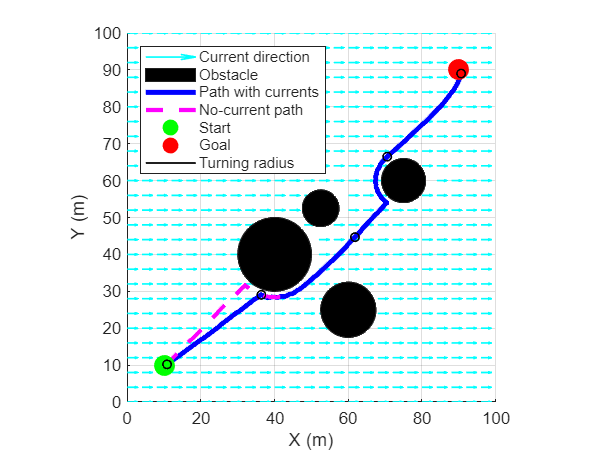

Computation time (with currents): 0.103 s
Computation time (no currents): 0.206 s


function apf_path_planning_wave_glider()
    % Artificial Potential Field Method for Local Path Planning
    % With Wave Glider Dynamics
    % Constant current, multiple static obstacles

    % Clear workspace
    clear; close all; clc;

    % Environment setup - 100x100m
    field_size = 100;
    resolution = 0.5;
    x = 0:resolution:field_size;
    y = 0:resolution:field_size;
    [X, Y] = meshgrid(x, y);

    % Robot parameters
    start_pos    = [10, 10];
    goal_pos     = [90, 90];
    robot_radius = 1.53;

    % WAVE GLIDER DYNAMICS PARAMETERS
    wave_glider.avg_speed      = 0.36;       % m/s
    wave_glider.turning_radius = 1.13;       % m
    wave_glider.max_turn_rate  = wave_glider.avg_speed / wave_glider.turning_radius; % rad/s

    % Obstacles [x, y, r]
    obstacles = [
        40, 40, 10;
        60, 25, 7.5;
        30, 75, 9;
        75, 60, 6;
        52.5, 52.5, 5
    ];

    % APF parameters
    k_att = 0.5;
    k_rep = 15;
    d0    = 20;
    dt    = 0.2;
    max_iterations = 10000;

    % Current (environment) parameters
    U_current = 0.1;   % m/s
    theta_rad = 0;     % 0 rad = east
    k_env     = 2;     % weight of environmental influence

    % Current vector field (constant)
    [Ux, Uy, phi_current] = uniform_current_field(X, Y, U_current, theta_rad);

    % Potentials (not directly plotted but kept for completeness)
    U_att   = attractive_potential(X, Y, goal_pos, k_att);
    U_rep   = repulsive_potential(X, Y, obstacles, k_rep, d0);
    U_env   = environmental_potential(X, Y, Ux, Uy, k_env);
    U_total = U_att + U_rep + U_env; %#ok<NASGU>

    % PATH WITH CURRENTS (baseline)
    t0 = tic;
    path_with_currents = path_planning_wave_glider_core(start_pos, goal_pos, obstacles, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, k_env, Ux, Uy, wave_glider);
    comp_time_with = toc(t0);

    % PATH WITHOUT CURRENTS (magenta): SAME PLANNER, k_env = 0
    k_env_nocurr = 0;
    t0 = tic;
    path_without_currents = path_planning_wave_glider_core(start_pos, goal_pos, obstacles, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, k_env_nocurr, Ux, Uy, wave_glider);
    comp_time_without = toc(t0);

    % Display wave glider parameters
    fprintf('\n--- Wave Glider Parameters ---\n');
    fprintf('Average Speed: %.2f m/s\n', wave_glider.avg_speed);
    fprintf('Turning Radius: %.2f m\n', wave_glider.turning_radius);
    fprintf('Max Turn Rate: %.3f rad/s (%.1f deg/s)\n', wave_glider.max_turn_rate, rad2deg(wave_glider.max_turn_rate));

    % Visualization
    visualize_results(X, Y, U_att, U_rep, U_env, start_pos, goal_pos, ...
        obstacles, path_with_currents, path_without_currents, field_size, Ux, Uy, phi_current, wave_glider);

    % Print computation times
    fprintf('Computation time (with currents): %.3f s\n', comp_time_with);
    fprintf('Computation time (no currents): %.3f s\n', comp_time_without);
end

%% Core WG Path Planner
function path = path_planning_wave_glider_core(start_pos, goal_pos, obstacles, ...
    k_att, k_rep, d0, dt, max_iter, robot_radius, k_env, Ux, Uy, wave_glider)

    % Local minima escape parameters
    stagnation_window     = 70;
    min_improve           = 0.5;
    force_eps             = 0.05;
    escape_angle_deg      = 85;
    escape_duration_sec   = 1;
    escape_steps_default  = max(1, round(escape_duration_sec / dt));

    % State
    current_pos     = start_pos;
    current_heading = 0;
    current_speed   = wave_glider.avg_speed;
    goal_threshold  = 1;

    path     = current_pos;
    headings = current_heading;

    % Progress tracking
    dist_hist = [];
    best_dist_recent = inf;
    no_improve_steps = 0;

    % Escape mode state
    escape_steps_left = 0;
    escape_sign       = 1;
    escape_angle_rad  = deg2rad(escape_angle_deg);

    % Constant current vector at any (x,y)
    c = [Ux(1,1), Uy(1,1)];

    fprintf('\nStarting wave glider path planning...\n');

    for iter = 1:max_iter
        % APF force at current position
        [Fx, Fy] = calculate_forces(current_pos, goal_pos, obstacles, ...
                                    k_att, k_rep, d0, k_env, c);

        % Stagnation detection
        dist_to_goal = norm(current_pos - goal_pos);
        dist_hist = [dist_hist; dist_to_goal]; %#ok<AGROW>
        if numel(dist_hist) > stagnation_window
            recent = dist_hist(end-stagnation_window+1:end);
            if (best_dist_recent - dist_to_goal) < min_improve
                no_improve_steps = no_improve_steps + 1;
            else
                no_improve_steps = 0;
            end
            best_dist_recent = min(best_dist_recent, dist_to_goal);

            if (no_improve_steps >= stagnation_window) || (hypot(Fx, Fy) < force_eps)
                escape_sign       = sign(randn); if escape_sign == 0, escape_sign = 1; end
                escape_steps_left = escape_steps_default;
                no_improve_steps  = 0;
            end
        else
            best_dist_recent = min(best_dist_recent, dist_to_goal);
        end

        % Escape rotation if active
        if escape_steps_left > 0
            [Fx, Fy] = rotate_vec(Fx, Fy, escape_sign * escape_angle_rad);
            escape_steps_left = escape_steps_left - 1;
        end

        % Heading update with turn-rate limit
        desired_heading   = atan2(Fy, Fx);
        heading_error     = angle_diff(desired_heading, current_heading);
        max_heading_change = wave_glider.max_turn_rate * dt;

        if abs(heading_error) > max_heading_change
            current_heading = current_heading + sign(heading_error)*max_heading_change;
        else
            current_heading = desired_heading;
        end
        current_heading = atan2(sin(current_heading), cos(current_heading));

        % Velocity including current effect (scaled by k_env inside force; here c only affects drift via body->ground)
        vx_body   = current_speed * cos(current_heading);
        vy_body   = current_speed * sin(current_heading);
        vx_ground = vx_body + c(1);
        vy_ground = vy_body + c(2);

        % NOTE: To isolate "no-current path", enforce k_env=0 (forces) AND zero drift by subtracting c here:
        if k_env == 0
            vx_ground = vx_body;  % remove drift so the path truly ignores currents
            vy_ground = vy_body;
        end

        % Position update
        next_pos = current_pos + dt * [vx_ground, vy_ground];

        % Collision check
        collision = false;
        for i = 1:size(obstacles, 1)
            oc = obstacles(i, 1:2); orad = obstacles(i, 3);
            if norm(next_pos - oc) < (orad + robot_radius)
                collision = true; break;
            end
        end

        if ~collision
            current_pos = next_pos;
            path = [path; current_pos]; %#ok<AGROW>
            headings = [headings; current_heading]; %#ok<AGROW>
        else
            % Try an avoidance nudge
            for turn_sign = [-1, 1]
                test_heading = current_heading + turn_sign * max_heading_change;
                test_vx_body = wave_glider.avg_speed * cos(test_heading);
                test_vy_body = wave_glider.avg_speed * sin(test_heading);
                if k_env == 0
                    test_vx = test_vx_body; test_vy = test_vy_body;
                else
                    test_vx = test_vx_body + c(1); test_vy = test_vy_body + c(2);
                end
                test_pos = current_pos + dt * [test_vx, test_vy];

                test_collision = false;
                for i = 1:size(obstacles, 1)
                    oc = obstacles(i, 1:2); orad = obstacles(i, 3);
                    if norm(test_pos - oc) < (orad + robot_radius)
                        test_collision = true; break;
                    end
                end
                if ~test_collision
                    current_heading = test_heading;
                    current_pos     = test_pos;
                    path = [path; current_pos]; %#ok<AGROW>
                    headings = [headings; current_heading]; %#ok<AGROW>
                    break;
                end
            end

            if collision
                escape_sign       = sign(randn); if escape_sign == 0, escape_sign = 1; end
                escape_steps_left = escape_steps_default;
            end
        end

        % Goal check
        if norm(current_pos - goal_pos) < goal_threshold
            fprintf('Goal reached in %d iterations with wave glider dynamics.\n', iter);
            break;
        end

    end

    if iter == max_iter
        fprintf('Maximum iterations reached. Goal may not be reachable with wave glider constraints.\n');
    end

    % Path statistics
    if size(path, 1) > 1
        path_length      = sum(vecnorm(diff(path), 2, 2));
        total_time       = size(path, 1) * dt;
        avg_ground_speed = path_length / total_time;

        fprintf('Wave Glider Path Stats:\n');
        fprintf('  Path length: %.2f m\n', path_length);
        fprintf('  Total time: %.1f s\n', total_time);
        fprintf('  Average ground speed: %.2f m/s\n', avg_ground_speed);
        fprintf('  Waypoints: %d\n', size(path,1));

        if length(headings) > 1
            heading_changes = diff(headings);
            heading_changes = atan2(sin(heading_changes), cos(heading_changes));
            total_turning = sum(abs(heading_changes));
            fprintf('  Total turning: %.2f rad (%.1f deg)\n', total_turning, rad2deg(total_turning));
        end
    end
end

%% Helpers
function diff = angle_diff(a1, a2)
    diff = a1 - a2;
    diff = atan2(sin(diff), cos(diff));
end

function [rx, ry] = rotate_vec(x, y, ang)
    ca = cos(ang); sa = sin(ang);
    rx = ca*x - sa*y;
    ry = sa*x + ca*y;
end

function U_att = attractive_potential(X, Y, goal, k_att)
    U_att = k_att * ((X - goal(1)).^2 + (Y - goal(2)).^2) / 2;
end

function U_rep = repulsive_potential(X, Y, obstacles, k_rep, d0)
    U_rep = zeros(size(X));
    for i = 1:size(obstacles, 1)
        obs_x = obstacles(i, 1); obs_y = obstacles(i, 2); obs_r = obstacles(i, 3);
        d_obs = sqrt((X - obs_x).^2 + (Y - obs_y).^2) - obs_r;
        inside_mask = d_obs <= 0;
        d_obs(inside_mask) = eps;
        mask = (d_obs > 0) & (d_obs <= d0);
        U_rep(mask) = U_rep(mask) + 0.5 * k_rep * ((1./d_obs(mask)) - (1/d0)).^2;
        U_rep(inside_mask) = 1000;
    end
end

function U_env = environmental_potential(X, Y, Ux, Uy, k_env)
    U_env = -k_env * (Ux .* X + Uy .* Y);
end

function [Ux, Uy, phi] = uniform_current_field(X, Y, U, theta_rad)
    cx = cos(theta_rad); sy = sin(theta_rad);
    Ux = U * cx * ones(size(X));
    Uy = U * sy * ones(size(Y));
    phi = U * (cx .* X + sy .* Y);
end

function [F_x, F_y] = calculate_forces(pos, goal, obstacles, k_att, k_rep, d0, k_env, c) %#ok<INUSD>
    x = pos(1); y = pos(2);
    F_att_x = -k_att * (x - goal(1));
    F_att_y = -k_att * (y - goal(2));

    F_rep_x = 0; F_rep_y = 0;
    for i = 1:size(obstacles, 1)
        ox = obstacles(i, 1); oy = obstacles(i, 2); orad = obstacles(i, 3);
        d_center = sqrt((x - ox)^2 + (y - oy)^2);
        d_obs = d_center - orad;

        if d_obs > 0 && d_obs <= d0
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);
            F_rep_mag = k_rep * (1/d_obs - 1/d0) * (1/d_obs^2);
            F_rep_x = F_rep_x + F_rep_mag * ux;
            F_rep_y = F_rep_y + F_rep_mag * uy;
        elseif d_obs <= 0
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);
            F_rep_x = F_rep_x + 100 * ux;
            F_rep_y = F_rep_y + 100 * uy;
        end
    end

    % Environmental force: constant push
    F_env_x = k_env * c(1);
    F_env_y = k_env * c(2);

    F_x = F_att_x + F_rep_x + F_env_x;
    F_y = F_att_y + F_rep_y + F_env_y;
end

%% Visualization
function visualize_results(X, Y, U_att, U_rep, U_env, start_pos, goal_pos, ...
    obstacles, path_with_currents, path_without_currents, field_size, Ux, Uy, phi_current, wave_glider) %#ok<INUSL>

    figure('Position', [100, 100, 800, 600]); hold on;

    % Current field arrows
    skip = 8;
    X_sub = X(1:skip:end, 1:skip:end);
    Y_sub = Y(1:skip:end, 1:skip:end);
    Ux_sub = Ux(1:skip:end, 1:skip:end);
    Uy_sub = Uy(1:skip:end, 1:skip:end);

    arrow_mask = true(size(X_sub));
    for i = 1:size(obstacles, 1)
        ox = obstacles(i, 1); oy = obstacles(i, 2); or = obstacles(i, 3);
        distances = sqrt((X_sub - ox).^2 + (Y_sub - oy).^2);
        arrow_mask = arrow_mask & (distances > or);
    end
    X_arrows = X_sub(arrow_mask);
    Y_arrows = Y_sub(arrow_mask);
    Ux_arrows = Ux_sub(arrow_mask);
    Uy_arrows = Uy_sub(arrow_mask);

    quiver(X_arrows, Y_arrows, Ux_arrows*4, Uy_arrows*4, ...
           0.5, 'Color', [0, 1, 1, 0.4], 'LineWidth', 1, 'DisplayName', 'Current direction');

    % Obstacles (solid black)
    for i = 1:size(obstacles, 1)
        cx = obstacles(i,1); cy = obstacles(i,2); cr = obstacles(i,3);
        th = linspace(0, 2*pi, 200);
        xf = cx + cr*cos(th); yf = cy + cr*sin(th);
        if i == 1
            fill(xf, yf, 'k', 'FaceAlpha', 1, 'DisplayName', 'Obstacle');
        else
            fill(xf, yf, 'k', 'FaceAlpha', 1, 'HandleVisibility','off');
        end
    end

    % Paths
    plot(path_with_currents(:,1),    path_with_currents(:,2),    'b-',  'LineWidth', 3,  'DisplayName', 'Path with currents');
    plot(path_without_currents(:,1), path_without_currents(:,2), 'm--', 'LineWidth', 2.5, 'DisplayName', 'No-current path');

    % Start / Goal
    plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 12, 'MarkerFaceColor','g', 'DisplayName','Start');
    plot(goal_pos(1),  goal_pos(2),  'ro', 'MarkerSize', 12, 'MarkerFaceColor','r', 'DisplayName','Goal');

    % Turning radius circles (for with-currents path only, as reference)
    if size(path_with_currents, 1) > 10
        n_circles = min(5, floor(size(path_with_currents, 1)/10));
        circle_indices = round(linspace(10, size(path_with_currents, 1)-5, n_circles));
        for idx = circle_indices
            pos = path_with_currents(idx, :);
            th = linspace(0, 2*pi, 50);
            circle_x = pos(1) + wave_glider.turning_radius * cos(th);
            circle_y = pos(2) + wave_glider.turning_radius * sin(th);
            if idx == circle_indices(1)
                plot(circle_x, circle_y, 'k', 'LineWidth', 1, 'DisplayName', 'Turning radius');
            else
                plot(circle_x, circle_y, 'k', 'LineWidth', 1, 'HandleVisibility', 'off');
            end
        end
    end

    % Axes & fonts
    xlabel('X (m)');
    ylabel('Y (m)');                 
    legend('show', 'Location', 'northwest');
    axis equal; xlim([0, field_size]); ylim([0, field_size]); grid on;
end

% Run the simulation
apf_path_planning_wave_glider();